# Plot Gas Prices

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the gas prices data and displays the variables.

countries = string(table2array(readtable("../data/gPrices.xlsx", "Sheet", "countries", "ReadVariableNames", false)));
prices = table2array(readtable("../data/gPrices.xlsx", "Sheet", "prices", "ReadVariableNames", false));
Year = table2array(readtable("../data/gPrices.xlsx", "Sheet", "Year", "ReadVariableNames", false));
whos

  Name            Size            Bytes  Class     Attributes

  Year           19x1               152  double              
  countries       1x10              668  string              
  prices         19x10             1520  double              



ctry = "Canada"

ctry = "Canada"

This code extracts the relevant data for a country.

idx = strcmp(ctry, countries);
ctryPrices = prices(:, idx)

ctryPrices =     1.8700
    1.9200
    1.7300
    1.5700
    1.4500
    1.5300
    1.6100
    1.6200
    1.3800
    1.5200


## Data Check

Check for missing data

if ~any(idx)
    errMsg = "No data available for " + ctry;
    error(errMsg)
elseif any(isnan(ctryPrices))
    warnMsg = "Missing values in price data for " + ctry + ".";
    warning(warnMsg)
end

This code plots the data.

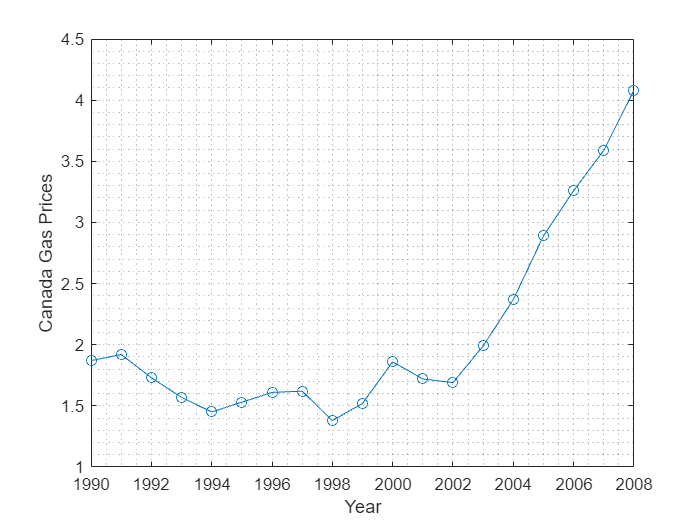

plot(Year,ctryPrices, "o-")
grid minor
xlabel("Year")
ylabel(ctry + " Gas Prices")